# **Sistemas de Vision Artificial. GII.**

**Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos.**

**Departamento de Electrónica. Universidad de Alcalá.**

**Hecho por: **

- Patricia Cuesta Ruiz

- Laura Mambrilla Moreno

# Tema 5: ejercicio 02 - k-Nearest Neighbour (kNN)

clc;
clear all;
close all;

- Calcule la especificidad y sensibilidad como: **especificidad = TN/(TN+FP)** y **sensibilidad = TP/(TP+FN)**, considerando como clase positiva (P) los fumadores ('Smoke'), para los siguientes valores de k = 1, 5, 10 (número k vecinos más cercanos).

**Para poder realizar este ejercicio necesitamos la matriz de confusión, la cual aporta los datos de TP, TN, FP y FN, identificados en la siguiente imagen. **

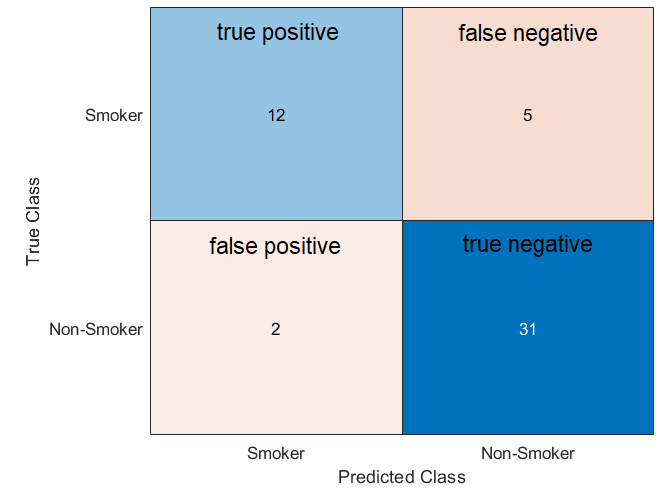

**En primer lugar realizamos la carga de datos de la** **base de datos **`hospital`**, que se ha dividido en dos grupos: 50% para entrenamiento y 50% para test.**

% base de datos 
load hospital;

% se utiliza solo la presión sanguinea
data = [hospital.BloodPressure]; 

% se clasifican los datos como 1 si es fumador y 0 si no lo es
HS = categorical(hospital.Smoker, [1 0], {'Smoker' 'Non-Smoker'});

rng(2) % control de números aleatorios

% se obtienen una distribución aleatoria de los índices del tamaño de los datos
idx = randperm(length(data))';

% 50% para entrenamiento y 50% para test
distribution_train = 0.5;
idx_train = idx(1:length(data)*distribution_train);
idx_test = idx(length(data)*distribution_train+1:length(data));

% valores y etiquetas para entrenamiento
data_train = data(idx_train, :);
label_train = HS(idx_train); % 'Smoker' = 1, 'Non-Smoker' = 0

tabulate(label_train)

       Value    Count   Percent
      Smoker       17     34.00%
  Non-Smoker       33     66.00%


% valores y etiquetas para test
data_test = data(idx_test, :);
label_test = HS(idx_test); % 'Smoker' = 1, 'Non-Smoker' = 0

tabulate(label_test)

       Value    Count   Percent
      Smoker       17     34.00%
  Non-Smoker       33     66.00%


**Visualizamos los datos utilizando un gráfico de dispersión.**

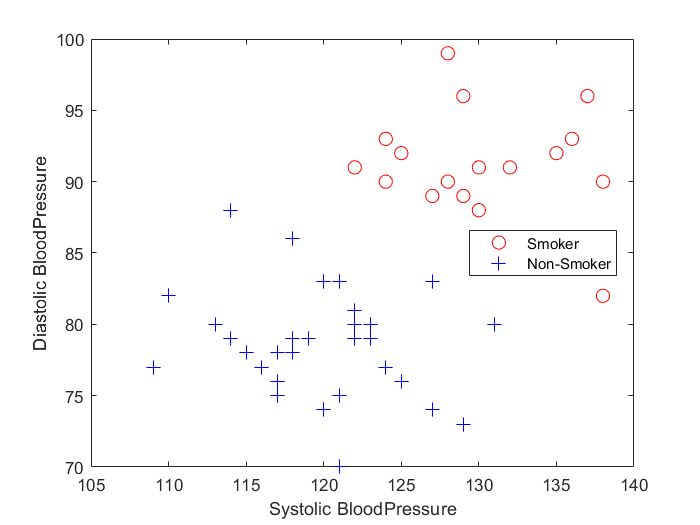

gscatter(data_train(:,1), data_train(:,2), label_train, 'rb', 'o+', 8, 'on')
xlabel('Systolic BloodPressure');
ylabel('Diastolic BloodPressure');
legend('Location', 'best');

# **CASO k = 1**

**Se realiza el entrenamiento del modelo.**

k_1 = 1;
model_kNN_1 = fitcknn(data_train, label_train, 'NumNeighbors', k_1);

**Visualizamos la matriz de confusión del modelo, que compara los valores verdaderos con las predicciones.**

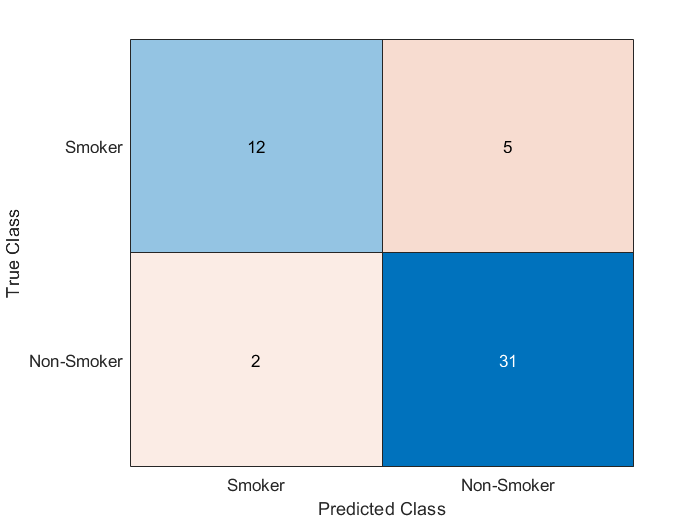

label_prediction_1 = predict(model_kNN_1, data_test);
confusion_mat_1 = confusionmat(label_test, label_prediction_1);
confusion_chart_1 = confusionchart(label_test, label_prediction_1);

% Parametros desglosados de la matriz de confusión
TP_1 = confusion_mat_1(1,1); % True positive
FP_1 = confusion_mat_1(1,2); % False positive
FN_1 = confusion_mat_1(2,1); % False negative
TN_1 = confusion_mat_1(2,2); % True negative

% Sensibilidad
TPR_1 = TP_1 / (TP_1 + FN_1)

TPR_1 = 0.8571

%Especificidad
SPC_1 = TN_1 / (FP_1 + TN_1) 

SPC_1 = 0.8611

# **CASO k = 5**

**Se realiza el entrenamiento del modelo.**

k_5 = 5;
model_kNN_5 = fitcknn(data_train, label_train, 'NumNeighbors', k_5);

**Visualizamos la matriz de confusión del modelo, que compara los valores verdaderos con las predicciones.**

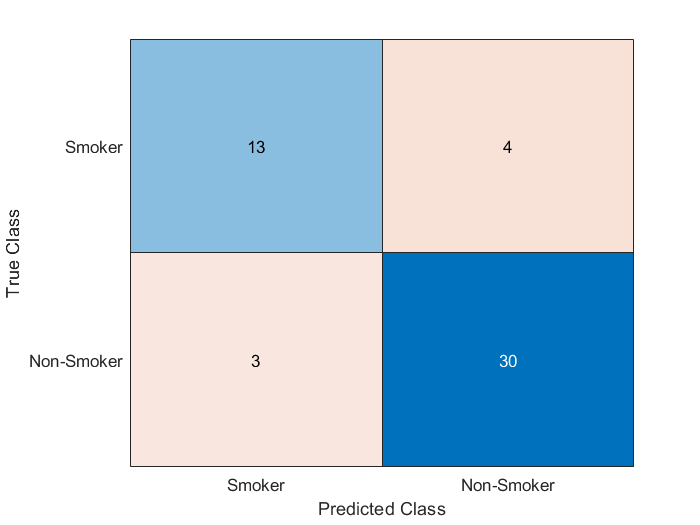

label_prediction_5 = predict(model_kNN_5, data_test);
confusion_mat_5 = confusionmat(label_test, label_prediction_5);
confusion_chart_5 = confusionchart(label_test, label_prediction_5);

% Parametros desglosados de la matriz de confusión
TP_5 = confusion_mat_5(1,1); % True positive
FP_5 = confusion_mat_5(1,2); % False positive
FN_5 = confusion_mat_5(2,1); % False negative
TN_5 = confusion_mat_5(2,2); % True negative

% Sensibilidad
TPR_5 = TP_5 / (TP_5 + FN_5)

TPR_5 = 0.8125

%Especificidad
SPC_5 = TN_5 / (FP_5 + TN_5) 

SPC_5 = 0.8824

# **CASO k = 10**

**Se realiza el entrenamiento del modelo.**

k_10 = 10;
model_kNN_10 = fitcknn(data_train, label_train, 'NumNeighbors', k_10);

**Visualizamos la matriz de confusión del modelo, que compara los valores verdaderos con las predicciones.**

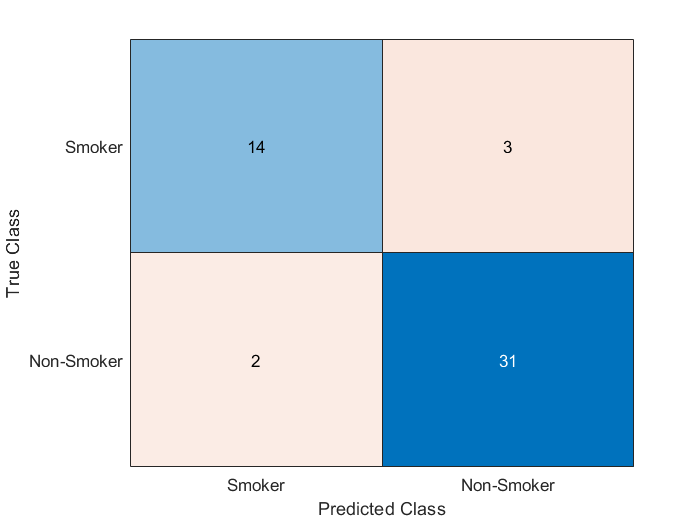

label_prediction_10 = predict(model_kNN_10, data_test);
confusion_mat_10 = confusionmat(label_test, label_prediction_10);
confusion_chart_10 = confusionchart(label_test, label_prediction_10);

% Parametros desglosados de la matriz de confusión
TP_10 = confusion_mat_10(1,1); % True positive
FP_10 = confusion_mat_10(1,2); % False positive
FN_10 = confusion_mat_10(2,1); % False negative
TN_10 = confusion_mat_10(2,2); % True negative

% Sensibilidad
TPR_10 = TP_10 / (TP_10 + FN_10)

TPR_10 = 0.8750

%Especificidad
SPC_10 = TN_10 / (FP_10 + TN_10) 

SPC_10 = 0.9118

# **Comparación **

**La sensibilidad representa la Tasa de True Positives, que es la proporción de casos positivos que han sido correctamente identificados. Se calcula con la siguiente fórmula:**

**sensibilidad = TP/(TP+FN) **

**que sería igual a decir sensibilidad = true positives/total fumadores.**

**La especificidad representa la Tasa de True Negatives, que es la proporción de casos negativos que han sido correctamente identificados. Se calcula con la siguiente fórmula:**

**especificidad = TN/(TN+FP)**

**que sería igual a decir especificidad = true negatives/total no fumadores.**

**A continuación se pueden observar las 3 matrices de confusión correspondientes a cada k estudiada.**

**                                              k = 1                                                                           k = 5                                                                         k = 10  **

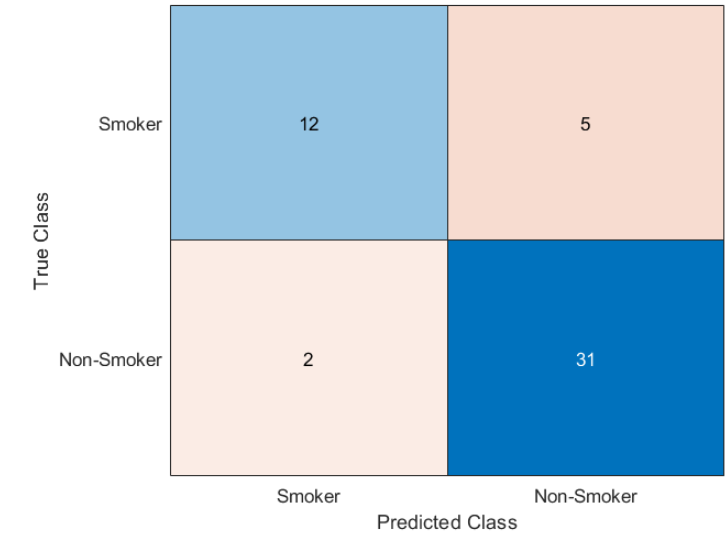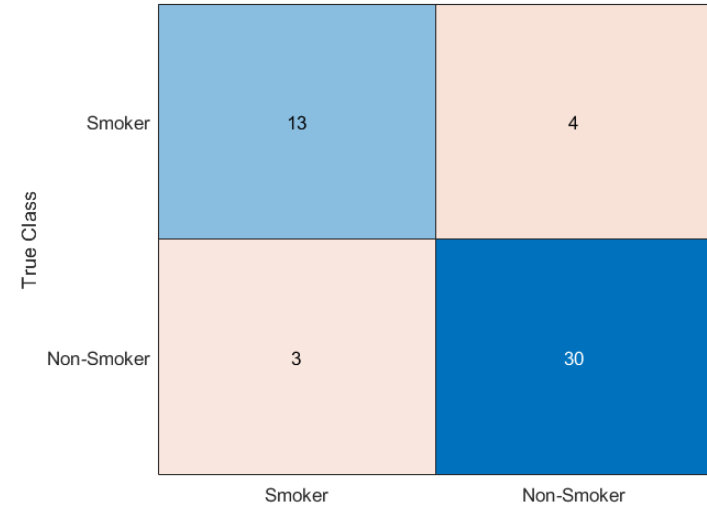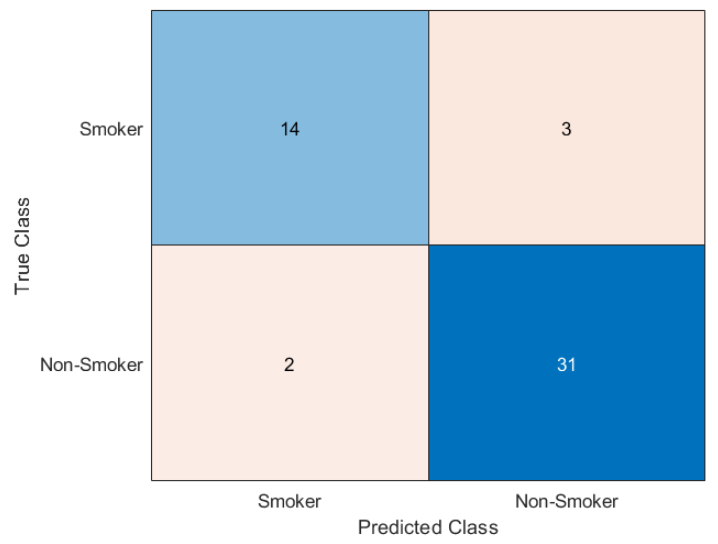

**En el siguiente código se muestran en dos listas los valores de las sensibilidades y especificidades calculadas con distintos ks.**

sensibilidades = [TPR_1; TPR_5; TPR_10]

sensibilidades =     0.8571
    0.8125
    0.8750


**Estudiando los valores de la lista *****sensibilidades*****,** **observamos que los datos que corresponden al número de fumadores identificados correctamente son:**

- **con k = 1, el 85,71%   **

- **con k = 5, el 81,25%**

- **con k = 10, el 87,20%**

especificidades = [SPC_1; SPC_5; SPC_10]

especificidades =     0.8611
    0.8824
    0.9118


**Estudiando los valores de la lista *****especificidades*****,** **observamos que los datos que corresponden al número de no fumadores identificados correctamente son:**

- **con k = 1, el 86,11%   **

- **con k = 5, el 88,24%**

- **con k = 10, el 91,18%**

**Con esta información cocluímos que con un k elevado (próximo a 10) los resultados son muy próximos a ser óptimos.**